%  ==  加权 PCA  ==  
clear all
% 执行主成分分析时，使用变量的逆方差作为权重。
% == Step1  加载样本数据集。
load hald

%== Step2  使用原料数据的逆方差作为变量权重执行主成分分析。
 [wcoeff,score,latent,~,explained] = pca(ingredients,'VariableWeights','variance')

wcoeff =    -2.7998    2.9940   -3.9736    1.4180
   -8.7743   -6.4411    4.8927    9.9863
    2.5240   -3.8749   -4.0845    1.7196
    9.1714    7.5529    3.2710   11.3273


score =     1.4672    1.9030    0.5300    0.0385
    2.1358    0.2384    0.2902   -0.0298
   -1.1299    0.1839    0.0107   -0.0937
    0.6599    1.5768   -0.1792   -0.0331
   -0.3588    0.4835    0.7401    0.0192
   -0.9666    0.1699   -0.0857   -0.0122
   -0.9307   -2.1348    0.1730    0.0083
    2.2321   -0.6917   -0.4597    0.0226
    0.3515   -1.4322    0.0316   -0.0450
   -1.6625    1.8281   -0.8512    0.0198


latent =     2.2357
    1.5761
    0.1866
    0.0016


explained =    55.8926
   39.4017
    4.6652
    0.0406



% 请注意，系数矩阵 wcoeff 不是正交矩阵。

% == Step3  计算正交系数矩阵。
coefforth = inv(diag(std(ingredients)))* wcoeff

coefforth =    -0.4760    0.5090   -0.6755    0.2411
   -0.5639   -0.4139    0.3144    0.6418
    0.3941   -0.6050   -0.6377    0.2685
    0.5479    0.4512    0.1954    0.6767


% 检查新系数矩阵 coefforth 的正交性。
% 正交矩阵和自己转制相乘以后对角线为1
 coefforth*coefforth'

ans =     1.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    1.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.0000


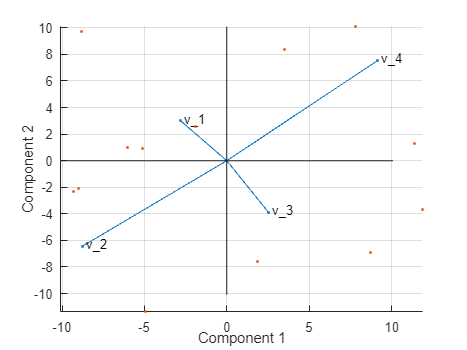

 
 % == Step4 画图
biplot(wcoeff(:,1:2),'scores',score(:,1:2),'varlabels',{'v_1','v_2','v_3','v_4'});

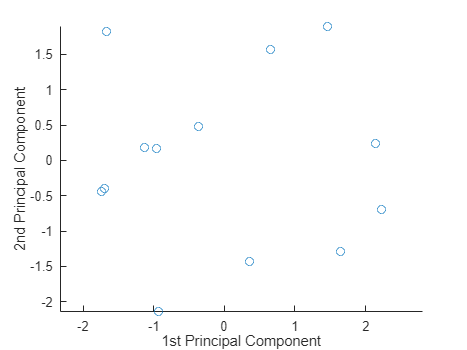


% figure;
% biplot(coefforth(:,1:2),'scores',score(:,1:2),'varlabels',{'v_1','v_2','v_3','v_4'});

figure;
scatter(score(:,1),score(:,2))
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')